# Restart and Initalize the Analysis

% Researt the system
clear all;
close all;
clc;

% Manage directory
cd('C:\Users\lluoz\Documents\ZJLalala\Research\paper_writing\data_analysis\20251217\data');
addpath('20251209', '20251210', '20251211', '20251212', '20251215', '20251216');

% Data loader
function trimmed_avg = trimmedmean(data, trimpct)

    if nargin < 2
        trimpct = 0.10;
    end

    data = data(:);              % ensure column vector
    data = sort(data);

    n = numel(data);
    k = floor(n * trimpct);      % points trimmed from each side
    k = min(k, floor((n-1)/2));  % safety protection

    trimmeddata = data(k+1 : n-k);
    trimmed_avg = mean(trimmeddata);
end

function [frequency, trapped, lost, act_rf] = readData(timestamp)

    frequency = readmatrix(timestamp + "_arr_of_setpoints");
    trapped   = readmatrix(timestamp + "_ratio_signal");
    lost      = readmatrix(timestamp + "_ratio_lost");
    act_rfs   = readmatrix(timestamp + "_act_RF_amplitude");
    
    act_rf = trimmedmean(act_rfs);

end

% Define data to load
scanRF = struct([]);

% ===== RF = 0.0 =====
scanRF(1).RF = 0.0;
scanRF(1).timestamps = {
    '20251209_170328'
    '20251209_171547'
    '20251209_172238'
    '20251209_174008'
    '20251209_180316'
};

% ===== RF = 0.5 =====
scanRF(2).RF = 0.5;
scanRF(2).timestamps = {
    '20251210_132650'
    '20251210_134258'
    '20251210_135743'
    '20251210_141831'
    '20251210_142612'   % overflow
    '20251210_143519'   % overflow
};

% ===== RF = 1.0 =====
scanRF(3).RF = 1.0;
scanRF(3).timestamps = {
    '20251210_182135'
    '20251210_182826'
    '20251210_184343'
    '20251210_185032'
    '20251210_185733'
};

% ===== RF = 1.0 (mistake run) =====
scanRF(4).RF = 1.0;
scanRF(4).timestamps = {
    '20251211_135746'
    '20251211_140326'
    '20251211_141307'
    '20251211_141920'
    '20251211_142521'
    '20251211_143512'
    '20251211_144252'
};

% ===== RF = 1.5 =====
scanRF(5).RF = 1.5;
scanRF(5).timestamps = {
    '20251211_162353'
    '20251211_163055'
    '20251211_164146'
    '20251211_164610'
};

% ===== RF = 2.0 =====
scanRF(6).RF = 2.0;
scanRF(6).timestamps = {
    '20251212_171614'
    '20251212_172308'
    '20251212_173612'
    '20251212_130011'
    '20251212_130740'
    '20251212_132040'
    '20251212_132653'
    '20251212_133223'
    '20251212_134210'
};

% ===== RF = 2.6 =====
scanRF(7).RF = 2.6;
scanRF(7).timestamps = {
    '20251212_183713'
    '20251212_184222'
    '20251212_184923'
    '20251212_185420'
    '20251212_191239'
    '20251212_192357'
};

% ===== RF = 3.3 =====
scanRF(8).RF = 3.3;
scanRF(8).timestamps = {
    '20251215_121232'
    '20251215_121921'
    '20251215_123555'
    '20251215_124102'
};

% ===== RF = 4.0 =====
scanRF(9).RF = 4.0;
scanRF(9).timestamps = {
    '20251215_140843'
    '20251215_141616'
    '20251215_143015'
};

% ===== RF = 5.0 =====
scanRF(10).RF = 5.0;
scanRF(10).timestamps = {
    '20251215_153823'
    '20251215_154627'
    '20251215_160259'
    '20251215_160758'
};

% ===== RF = 6.0 =====
scanRF(11).RF = 6.0;
scanRF(11).timestamps = {
    '20251215_173206'
    '20251215_174013'
    '20251215_175327'
    '20251215_175907'
};

% ===== RF = 8.0 =====
scanRF(12).RF = 8.0;
scanRF(12).timestamps = {
    '20251216_140715'
    '20251216_141520'
    '20251216_142522'
    '20251216_143214'
};

% ===== RF = 8.0 (Mistake) =====
scanRF(13).RF = 8.0;
scanRF(13).timestamps = {
    '20251216_151946'
    '20251216_152803'
    '20251216_154005'
    '20251216_154620'
};

% Load data
dataMap = containers.Map('KeyType','char','ValueType','any');

for k = 1:numel(scanRF)
    RF_value = scanRF(k).RF;
    ts_list  = scanRF(k).timestamps;

    for j = 1:numel(ts_list)
        ts = ts_list{j};

        [freq, trapped, lost, measured_RF_power] = readData(ts);

        dataMap(ts) = struct( ...
            'timestamp', ts, ...
            'RF_set',    RF_value, ...
            'RF_meas',   measured_RF_power, ...
            'frequency', freq, ...
            'trapped',   trapped, ...
            'lost',      lost ...
        );
    end
end

clearvars freq trapped lost ts j k RF_value ts_list measured_RF_power

% Initialize saving structure
all_results = containers.Map('KeyType','char','ValueType','any');

## Refresh x and y, and then preview

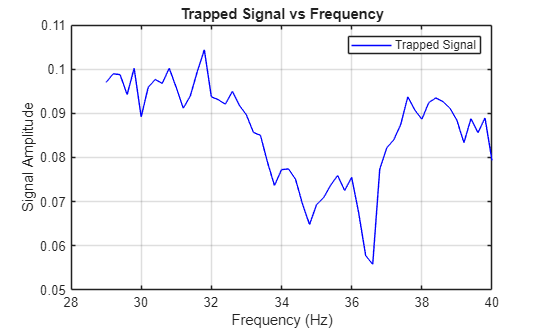

timestamp_to_analyze = "20251210_132650";

x = dataMap(timestamp_to_analyze).frequency;
y_lost = dataMap(timestamp_to_analyze).lost;
y_trapped = dataMap(timestamp_to_analyze).trapped;

% ===== Trapped signal =====
figure;
plot(x, y_trapped, 'b-', 'DisplayName', 'Trapped Signal');
xlabel('Frequency (Hz)');
ylabel('Signal Amplitude');
title('Trapped Signal vs Frequency');
legend show;
grid on;

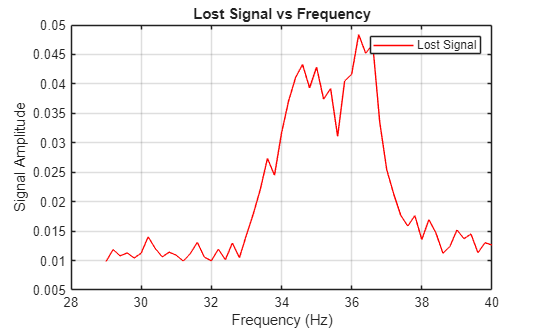


% ===== Lost signal =====
figure;
plot(x, y_lost, 'r-', 'DisplayName', 'Lost Signal');
xlabel('Frequency (Hz)');
ylabel('Signal Amplitude');
title('Lost Signal vs Frequency');
legend show;
grid on;

## You need to perform fitting manually in the curve fitter tool here

% Go to the curve fitter tool and work on it, then export to workspace

## Export and Save Results

% Metadata (enter manually)
data_types = {"trapped", "lost"}

data_types = 1×2 cell array
    {["trapped"]}    {["lost"]}


fitting_data = data_types{1};
model_lists = {"gaussian", "double_gaussian", "triple_gaussian"};
fitting_model = model_lists{2};

% Extract Results
param_names = coeffnames(fittedmodel);
param_values = coeffvalues(fittedmodel);
CI95 = confint(fittedmodel);
CI68 = confint(fittedmodel, 0.6827);
param_CI95_width = (CI95(2,:) - CI95(1,:) / 2);
param_uncertainties = (CI68(2,:) - CI68(1,:)) / 2;

% Store Results in structure
result = struct();

result.timestamp     = timestamp_to_analyze;
result.data_type     = fitting_data;
result.model         = fitting_model;

result.fittedmodel = fittedmodel;
result.goodness    = goodness;
result.output      = output;

result.parameters = table( ...
    param_values(:), ...
    param_uncertainties(:), ...
    param_CI95_width(:), ...
    CI95(1,:)', ...
    CI95(2,:)', ...
    'VariableNames', {'Value','Sigma1','CI95_width','CI95_low','CI95_high'}, ...
    'RowNames', param_names ...
);

key = timestamp_to_analyze + "_" + fitting_data + "_" + fitting_model;
all_results(key) = result;

% Printout current keys of all_results
ks = keys(all_results);
fprintf('%s\n', ks{:});

20251209_170328_lost_double_gaussian
20251209_170328_lost_gaussian
20251209_170328_trapped_gaussian
20251209_171547_lost_double_gaussian
20251209_171547_lost_gaussian
20251209_171547_trapped_double_gaussian
20251209_171547_trapped_gaussian
20251209_172238_lost_double_gaussian
20251209_172238_lost_gaussian
20251209_172238_trapped_gaussian
20251209_174008_lost_double_gaussian
20251209_174008_trapped_double_gaussian
20251209_180316_lost_gaussian
20251209_180316_trapped_double_gaussian
20251209_180316_trapped_gaussian



% Release names for code reuse (avoid auto rename behavior on the GUI)
clearvars fittedmodel goodness output data_types fitting_data model_lists fitting_model param_values param_names CI95 CI68 param_CI95_width param_uncertainties result key ks;

## Copy and Paste Zone for the GUI Fitter

models = containers.Map('KeyType','char','ValueType','char');
models("gaussian") = "amp1*exp(-(x-center1)^2/sigma1^2)+base";
models("double_gaussian") = "amp1*exp(-(x-center1)^2/sigma1^2)+amp2*exp(-(x-center2)^2/sigma2^2)+base";
models("triple_gaussian") = "amp1*exp(-(x-center1)^2/sigma1^2)+amp2*exp(-(x-center2)^2/sigma2^2)+amp3*exp(-(x-center3)^2/sigma3^2)+base"